# grpandplot v1.0.0 Documentation

`grpandplot`**: An open-source MATLAB tool for drawing box plot and violin plot with automatic multi-way data grouping.**

## Introduction

`grpandplot` features data grouping by multiple factors, supporting up to three-way grouping. Different combination of data objects (i.e. scatter (data points, box plot, violin plot, n number) can be plotted on top of each other with size and position automatically adjusted. This function is compatible with MATLAB's plotting syntax and can be combined with other MATLAB Graphics objects, such as `Figure`, `TiledChartLayout`  and `Axes`.  Moreover, figures are fully configurable with MATLAB's graphics methods and properties.

Features:

- Multi-way data grouping up to three factors

- Data can be grouped and displayed as groups along x-axis, of different colors and/or in separate tiles (i.e. axes) in the same figure

- Available data objects: scatter, box plot, violin plot, n number

- Data points jittered according to their PDF

- Different combinations of data objects allowed

- Size and position of data objects automatically adjusted

- Options available for adjust color, size and position

- Compatible with MATLAB's Graphics objects such as `Figure`, `TiledChartLayout`  and `Axes`

- Figures configurable via MATLAB's graphics methods and properties

Man Ho Wong, 2022.

## 1 Prep the data

In the following examples, we will use the `carbig.mat `dataset from MATLAB. We will first load the whole dataset into the Workspace. Since `grpandplot` only works with table, we will generate a table by joining the variables `org, Model_Year, when, cyl4, Acceleration, Horsepower, `and` Weight`. (Each of these variables is simply an array of values.)

load carbig.mat
cars = table(org,Model_Year,when,cyl4,Acceleration,Horsepower,Weight);

% display first 15 rows of the table 'cars' as an example
disp(cars(1:15,:))

      org      Model_Year    when     cyl4     Acceleration    Horsepower    Weight
    _______    __________    _____    _____    ____________    __________    ______

    USA            70        Early    Other          12           130         3504 
    USA            70        Early    Other        11.5           165         3693 
    USA            70        Early    Other          11           150         3436 
    USA            70        Early    Other          12           150         3433 
    USA            70        Early    Other        10.5           140         3449 
    USA            70        Early    Other          10           198         4341 
    USA            70        Early    Other           9           220         4354 
    U

That's it! The data is ready for plotting.

## 2 Grouping data

### 2.1 No grouping

Let's try to use `grpandplot` to plot "Weight" with default settings and no grouping. The first two input arguments of the function, `data` (table containing the data and grouping info)  and `yCol` (column to plot as y-value), are mandatory. They must be placed as the first and the second argument respectively. Other optional input arguments shown in this document can be placed in any order.

close all  % close all figures
grpandplot(cars,"Weight");  % plot column "Weight" in "cars"

By default, a box plot will be plotted with data points (jittered according to their PDF) shown on top of the box plot. When there is no grouping of data along the x-axis,'x' will be shown as the group label. The `yCol `name will be used as the y-axis title. To overwrite the default y-axis title, use the `yTitle` Name-Value pair.

`grpandplot(data, yCol, Name=Value);`

Name-Value pair can be specified in one of these formats:

`Name=Value`

`'Name',Value`

The value of `yTitle` must be: a string (scalar) or a character array.

For example, change the y-axis title to 'Weight (pounds)':

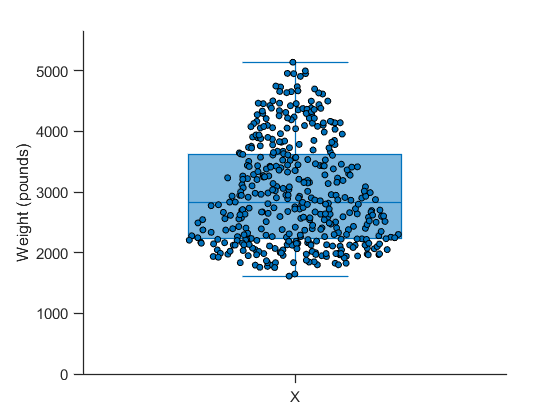

close all

grpandplot(cars,"Weight",yTitle='Weight (pounds)',yTitle='Weight (pounds)');

### 2.2 Group data and display groups along x-axis

To group the data and display the groups along x-axis, add the `xFactor` Name-Value pair.

`xFactor=[String (scalar) | Character array] `

 For example, to group the data by the factor "when":

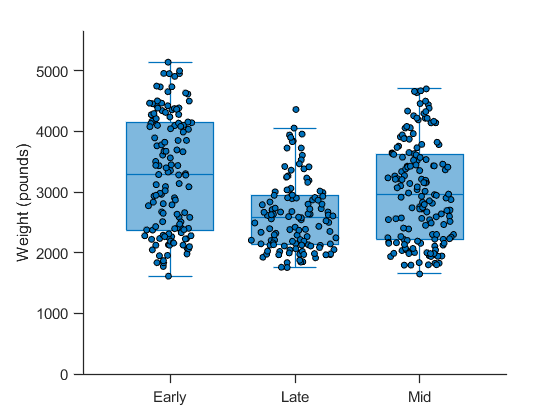

close all
grpandplot(cars,"Weight",yTitle='Weight (pounds)',xFactor="when");

### 2.3 Group data and display groups with different colors

grpandplot supports multi-way grouping. In addition to `xFactor`, add the Name-Value pair `cFactor` to group data and display groups with different colors.

For example, group data by "when" and "org":

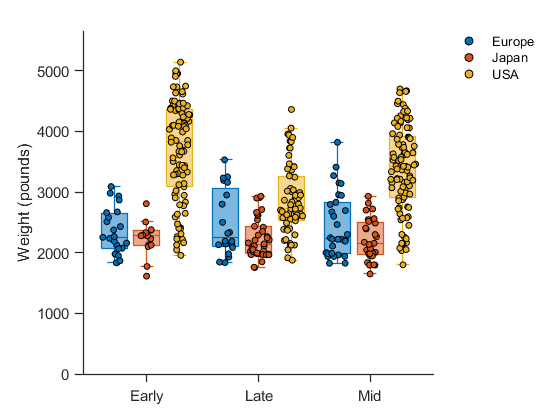

close all

grpandplot(cars,"Weight",yTitle='Weight (pounds)',xFactor="when",cFactor="org");

### 2.4 Group data and display groups in different tiles (subplots)

Likewise, add `tFactor` to group data and display groups in different tiles. You can specify the layout (arrangement of tiles in rows and columns) via the `nRow` (number of rows) and `nCol` (number of columns) options.

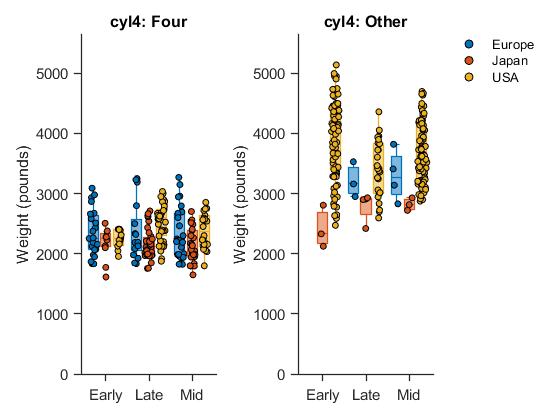

close all

grpandplot(cars,"Weight",yTitle='Weight (pounds)',xFactor="when",cFactor="org",tFactor="cyl4",nRow=1,nCol=2);

### 2.5 Specify group order

In the above examples, you may notice that groups along x-axis are plotted in this order: Early, Late and Mid, instead of chronological order. This is because groups are plotted in alphabetical order by default. Add the following name-value pairs to specify the x-axis, color or tile order:

 For example, to plot groups along x-axis in this order: Early, Mid, Late, add `xOrder `option:

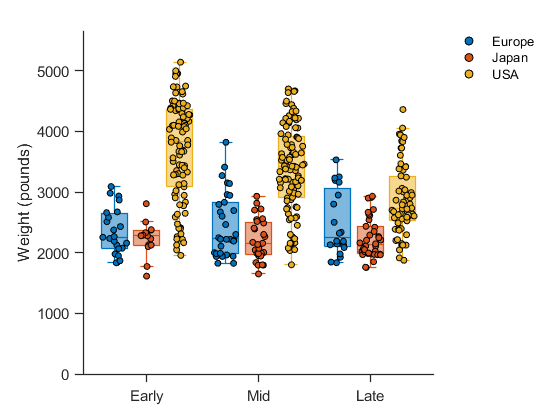

close all

whenOrder = {'Early','Mid','Late'};
grpandplot(cars,"Weight",yTitle='Weight (pounds)',xFactor="when",cFactor="org",xOrder=whenOrder);

## 3 Objects to show/hide in figure

### 3.1 Group separator

Add lines to separate groups along x-axis by setting the option `showXLine` to `true`:

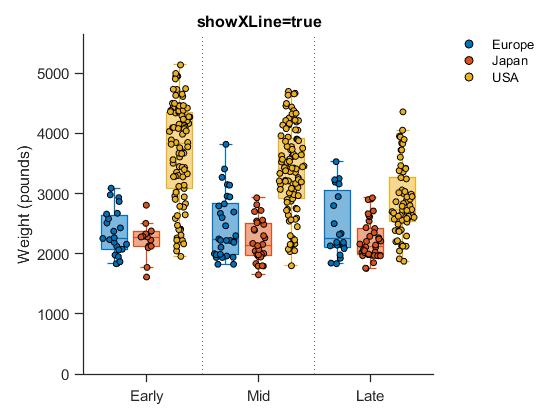

close all

whenOrder = {'Early','Mid','Late'};
grpandplot(cars,"Weight",yTitle='Weight (pounds)',xFactor="when",cFactor="org",xOrder=whenOrder,showXLine=true);
title('showXLine=true')

### 3.2 Show violin plot instead of box plot

 Set the option `showVln` to `true` and `showBox` to `false`:

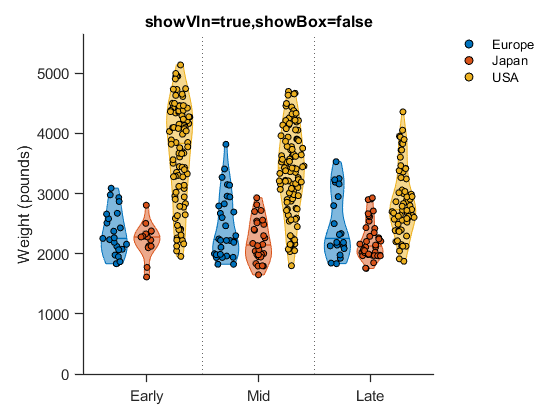

close all

whenOrder = {'Early','Mid','Late'};
grpandplot(cars,"Weight",yTitle='Weight (pounds)',xFactor="when",cFactor="org",xOrder=whenOrder, ...
           showXLine=true,showVln=true,showBox=false);
title('showVln=true,showBox=false')

### 3.3 Show n number of each group

 Set the option `showNum` to `true` and numYPos to a desired y-position (unit same as data):

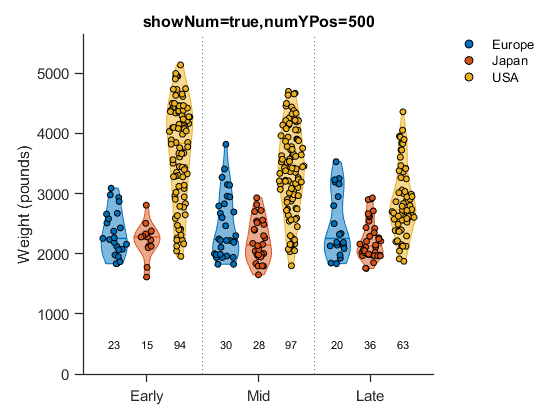

close all

whenOrder = {'Early','Mid','Late'};
grpandplot(cars,"Weight",yTitle='Weight (pounds)',xFactor="when",cFactor="org",xOrder=whenOrder, ...
           showXLine=true,showVln=true,showBox=false,showNum=true,numYPos=500);
title('showNum=true,numYPos=500')

### 3.3 Show/hide other objects

To show or hide objects, simply set the respective Name-Value pairs to `true` or `false`. Here is a list of objects available:

Value must be `logical` (accept `true`, `false`, 0, 1)

- `showPnt` : Data points (default: `true`)

- `showBox` : Box plot (default: `true`)

- `showVln` : Violin plot (default: `false`)

- `showOutlier` : Box plot outliers (default: `false`)

- `showXLine` : Vertical line separating groups allow x-axis. 

-                     Only works if grouping by `xFactor` is active.

-                     (default: `false`)

-  `showLegend` : Legend (default: `true`)

- `showNum` : n number (number of data points) (default: `false`)

## 4 Object position and size

### 4.1 Control data points z-position

For example, set `pntOnTop to false `(default: `true`) to plot data points below other objects:

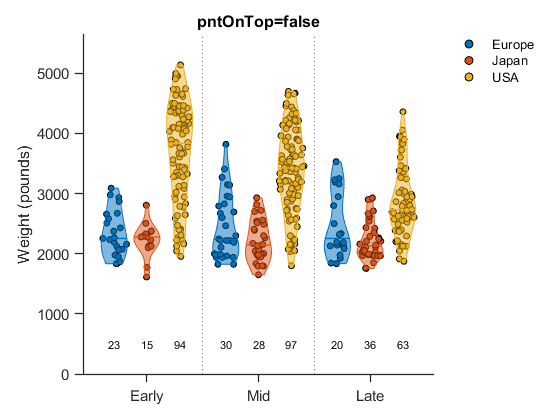

close all

whenOrder = {'Early','Mid','Late'};
grpandplot(cars,"Weight",yTitle='Weight (pounds)',xFactor="when",cFactor="org",xOrder=whenOrder, ...
           showXLine=true,showVln=true,showBox=false,showNum=true,numYPos=500,pntOnTop=false);
title('pntOnTop=false')

### 4.2 Specify data point size

Use the `pntSize` option to change the size of data points. For example, set the size to 5 (default: `20`):

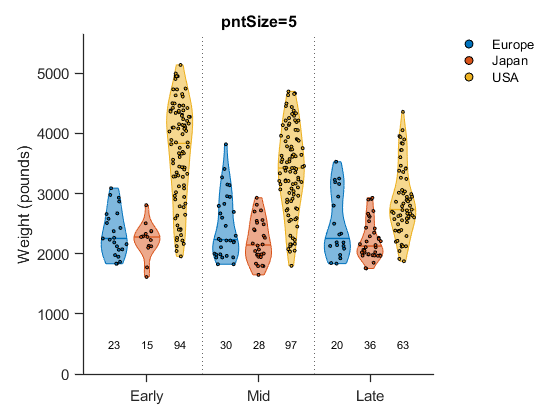

close all

whenOrder = {'Early','Mid','Late'};
grpandplot(cars,"Weight",yTitle='Weight (pounds)',xFactor="when",cFactor="org",xOrder=whenOrder, ...
           showXLine=true,showVln=true,showBox=false,showNum=true,numYPos=500,pntSize=5);
title('pntSize=5')

### 4.3 Specify width of data objects

Use the `w` option to change the width of data objects (data points, box plot and violin plot). All objects will have the same width (Default: `0.7` for 0 or 1 color group; `0.7/3` for 3 color groups).

The value is relative to the width between two x-axis labels.

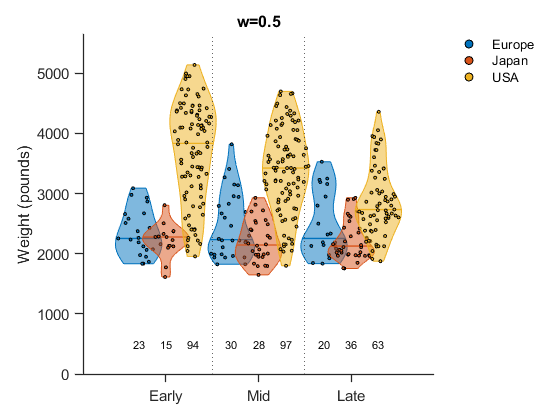

close all

whenOrder = {'Early','Mid','Late'};
grpandplot(cars,"Weight",yTitle='Weight (pounds)',xFactor="when",cFactor="org",xOrder=whenOrder, ...
           showXLine=true,showVln=true,showBox=false,showNum=true,numYPos=500,pntSize=5,w=0.5);
title('w=0.5')

### 4.4 Adjust space between data objects

Use the `gap` option to adjust the space between data objects of the same x-axis group (Default: `2.2` for 0 or 1 color group; `2.2/3` for 3 color groups).

The value is relative to number of color groups.

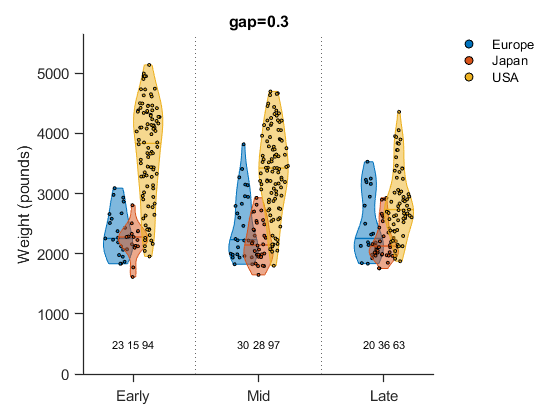

close all

whenOrder = {'Early','Mid','Late'};
grpandplot(cars,"Weight",yTitle='Weight (pounds)',xFactor="when",cFactor="org",xOrder=whenOrder, ...
           showXLine=true,showVln=true,showBox=false,showNum=true,numYPos=500,pntSize=5,gap=0.3);
title('gap=0.3')

### 4.5 Adjust horizontal scale of figure

Use the `xSpace` option to adjust the space between data objects and the ends of x-axis. You can adjust the horizontal scale of the figure by adjusting the x-axis length. (Default: `0`)

The value is relative to the width between two x-axis labels.

For example, add extra space to both ends of the x-axis to scale down all data objects horizontally:

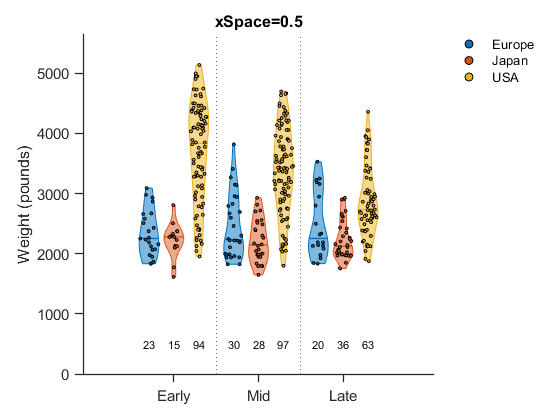

close all

whenOrder = {'Early','Mid','Late'};
grpandplot(cars,"Weight",yTitle='Weight (pounds)',xFactor="when",cFactor="org",xOrder=whenOrder, ...
           showXLine=true,showVln=true,showBox=false,showNum=true,numYPos=500,pntSize=5,xSpace=0.5);
title('xSpace=0.5')

## 5 Color

### 5.1 Color map

Use the `cmap` option to specify the colors of data objects if data is grouped into different colors; Otherwise, the first color in `cmap `will be used for all data objects.

`cmap = [Rows of RGB triplets] (default : MATLAB's "lines")`

Use RGB triplets. For example, [0 0 0; 1 0 0; 0 0 1] equals black, red and blue.

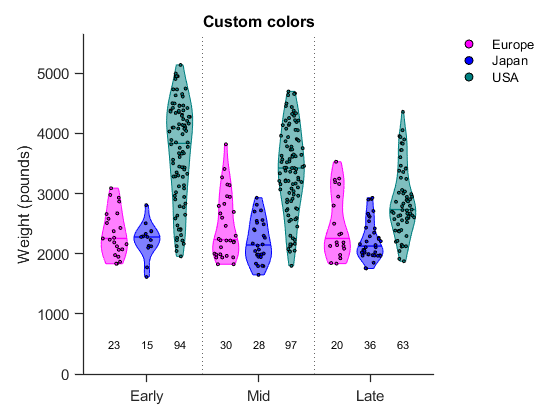

close all

colors = [1 0 1; 0 0 1; 0 .5 .5];
whenOrder = {'Early','Mid','Late'};
grpandplot(cars,"Weight",yTitle='Weight (pounds)',xFactor="when",cFactor="org",xOrder=whenOrder, ...
           showXLine=true,showVln=true,showBox=false,showNum=true,numYPos=500,pntSize=5,cmap=colors);
title('Custom colors')

### 5.2 Data object fill color and edge color

Change data object fill color and edge color using the following Name-Value pairs:

Value must be an RGB triplet

- `pntFillC` : Overwrite fill color of data points with custom color.

- `boxFillC` : Overwrite fill color of box plots with custom color.

- `vlnFillC` : Overwrite fill color of violin plots with custom color.

- `pntEdgeC` : Overwrite edge color of data points with custom color. (Default: black)

- `boxEdgeC` : Overwrite edge color of box plots with custom color.

- `vlnEdgeC` : Overwrite edge color of violin plots with custom color.

For example, use `cmap `as the color map for all object, but change the data point fill color to black:

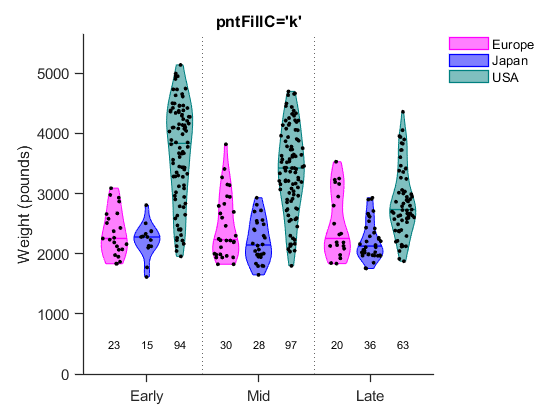

close all

colors = [1 0 1; 0 0 1; 0 .5 .5];
whenOrder = {'Early','Mid','Late'};
grpandplot(cars,"Weight",yTitle='Weight (pounds)',xFactor="when",cFactor="org",xOrder=whenOrder, ...
           showXLine=true,showVln=true,showBox=false,showNum=true,numYPos=500,pntSize=5, ...
           cmap=colors,pntFillC='k');
title('pntFillC=''k''')

### 5.3 Data object fill color transparency

Change data object fill color transparency using the following Name-Value pairs:

Value must be a positive number between 0-1. (0 = full transparency.)

- `pntAlpha` : Transparency of data points. (default: 1)

- `boxAlpha` : Transparency of box plots. (default: 0.5)

- `vlnAlpha` : Transparency of violin plots. (default: 0.5)

For example, set violin plots to transparent:

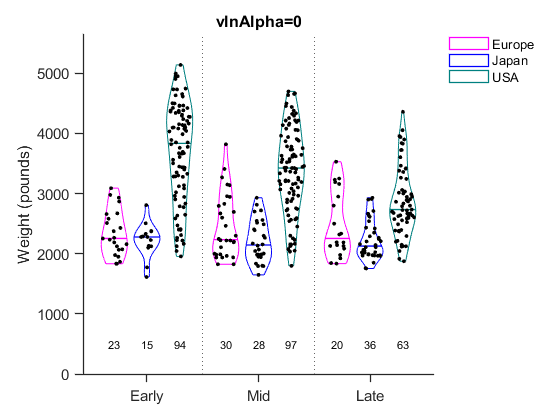

close all

colors = [1 0 1; 0 0 1; 0 .5 .5];
whenOrder = {'Early','Mid','Late'};
grpandplot(cars,"Weight",yTitle='Weight (pounds)',xFactor="when",cFactor="org",xOrder=whenOrder, ...
           showXLine=true,showVln=true,showBox=false,showNum=true,numYPos=500,pntSize=5, ...
           cmap=colors,pntFillC='k',vlnAlpha=0);
title('vlnAlpha=0')

## 6 Plotting with other MATLAB Graphics objects

### 6.1 Assign graph to a parent object

You can assign the graph to a parent object using the `parent` Name-Value pair. The parent object can be an `Axes` object, a `figure` object or a tiled Chart layout.

- If no `parent` is specified, a new figure will be created by default. The layout of the tiles (number of rows and columns) will follow the `nRow` and `nCol` settings if they are provided.

- If `parent` is a `figure` object, the tile layout will follow the `nRow` and `nCol` settings if they are provided.

- If `parent` is a tiled chart layout, the tile layout will follow the layout of `parent`, ignoring the `nRow` and `nCol` settings.

- If `parent` is an `Axes` object, grouping data in separate tiles will not be supported.

Specifying a parent object allows you to have more control of the position, size and layout of the figure.

### 6.2 Figure as a parent object

For example, set figure dimensions by assigning the graph to a `figure` object with size = 800x300 px:

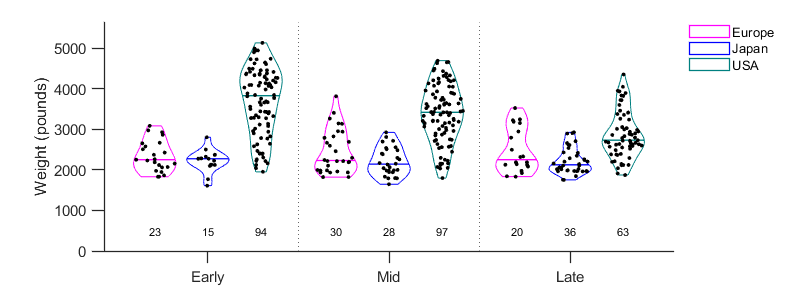

close all

% create a figure of size 800 x 300
fig = figure("Position",[0 0 800 300]);

colors = [1 0 1; 0 0 1; 0 .5 .5];
whenOrder = {'Early','Mid','Late'};
grpandplot(cars,"Weight",yTitle='Weight (pounds)',xFactor="when",cFactor="org",xOrder=whenOrder, ...
           showXLine=true,showVln=true,showBox=false,showNum=true,numYPos=500,pntSize=5, ...
           cmap=colors,pntFillC='k',vlnAlpha=0,parent=fig);  % fig is the parent

### 6.3 Tiled chart layout as a parent object

Assign the graph to a tiled chart layout to customize the layout of tiles (when data is grouped into different tiles):

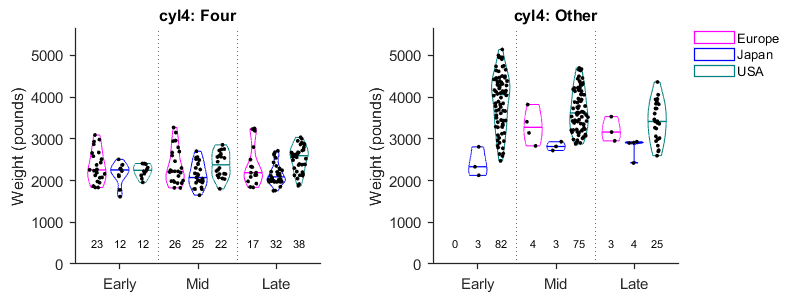

close all
% create a figure of size 800 x 300
fig = figure("Position",[0 0 800 300]);

% Custom layout; a child of fig
layout = tiledlayout(1,2,Padding="compact",TileSpacing="loose");  % this layout allows 1 x 2 tiles

colors = [1 0 1; 0 0 1; 0 .5 .5];
whenOrder = {'Early','Mid','Late'};
grpandplot(cars,"Weight",yTitle='Weight (pounds)',xFactor="when",cFactor="org",xOrder=whenOrder, tFactor="cyl4",...
           showXLine=true,showVln=true,showBox=false,showNum=true,numYPos=500,pntSize=5, ...
           cmap=colors,pntFillC='k',vlnAlpha=0,nRow=2,nCol=1,parent=layout);  % layout is the parent; nCol and nRow are ignored

### 6.4 Nested layout

You can assign the parent as a child of another graphics object to create a nested layout. In the following example, the tiles are plotted in `sublayout`, which is a child of `mainlayout`. s`ublayout` occupies tile 2 and 3 of `mainlayout`:

close all

% figure
fig = figure("Position",[0 0 800 450]);

% layout is a child of fig
mainlayout = tiledlayout(fig,2,3,Padding="compact",TileSpacing="loose");  % this layout allows 2 x 3 tiles

% sublayout is a child of layout
sublayout = tiledlayout(mainlayout,1,2,Padding="tight",TileSpacing="tight");  % this layout allows 1 x 2 tiles
sublayout.Layout.Tile = 2;  % Location (tile number) in mainlayout (i.e. sublayout starts at tile 2 of mainlayout) 
sublayout.Layout.TileSpan = [1 2]; % this layout span aross rows x columns in mainlayout (i.e. tile 2 and 3 of mainlayout)

After setting up the layout structure, you can assign `sublayout` as the parent object:

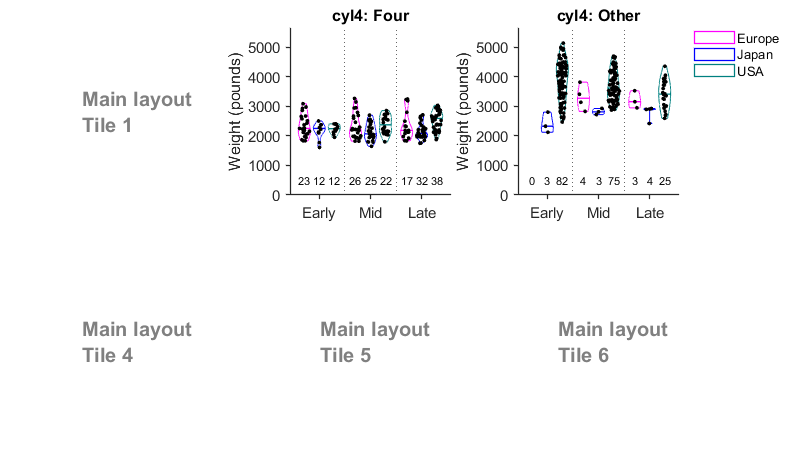

colors = [1 0 1; 0 0 1; 0 .5 .5];
whenOrder = {'Early','Mid','Late'};
grpandplot(cars,"Weight",yTitle='Weight (pounds)',xFactor="when",cFactor="org",xOrder=whenOrder, tFactor="cyl4",...
           showXLine=true,showVln=true,showBox=false,showNum=true,numYPos=500,pntSize=5, ...
           cmap=colors,pntFillC='k',vlnAlpha=0,nRow=2,nCol=1,parent=sublayout);  % sublayout is the parent

%%
% Number all other tiles in mainlayout for illustration
nexttile(mainlayout);  % go back to mainlayout and add a tile
text(0.2,0.5,{'Main layout', 'Tile 1'},FontSize=15,Color=[.5 .5 .5],FontWeight='bold'); axis off
nexttile;
text(0.2,0.5,{'Main layout', 'Tile 4'},FontSize=15,Color=[.5 .5 .5],FontWeight='bold'); axis off
nexttile;
text(0.2,0.5,{'Main layout', 'Tile 5'},FontSize=15,Color=[.5 .5 .5],FontWeight='bold'); axis off
nexttile;
text(0.2,0.5,{'Main layout', 'Tile 6'},FontSize=15,Color=[.5 .5 .5],FontWeight='bold'); axis off

### 6.5 Axes as a parent object

You can assign the graph to an `Axes` object. For example, you can plot the graph in an inset of another figure. In the following example, we will plot the graph inside an histogram.

fig = figure(Position=[0 0 600 400]);
colors = [1 0 1; 0 0 1; 0 .5 .5];
hold on

% Plot histogram
histogram(cars.Weight(cars.org=='E'),20,"Normalization","pdf","DisplayStyle","stairs","EdgeColor",colors(1,:),DisplayName='Europe')
histogram(cars.Weight(cars.org=='J'),20,"Normalization","pdf","DisplayStyle","stairs","EdgeColor",colors(2,:),DisplayName='Japan')
histogram(cars.Weight(cars.org=='U'),20,"Normalization","pdf","DisplayStyle","stairs","EdgeColor",colors(3,:),DisplayName='USA')
ylabel('PDF');
xlabel('Weight (pounds)');
legend('Location','bestoutside',Box='off')

After plotting the main figure (histogram), create an `Axes` object as an inset and assign it as the parent object:

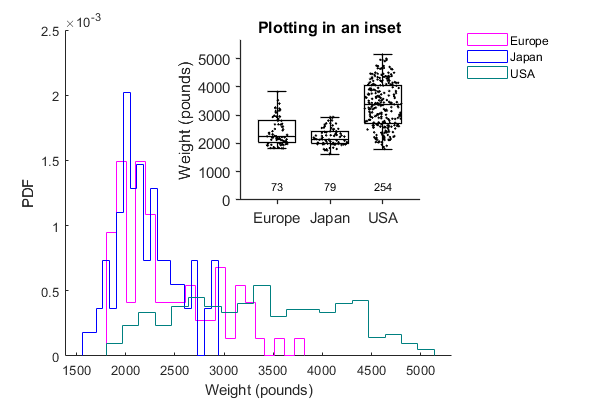

% create an inset in histogram
inset = axes("Position",[0.4,0.5,0.3,0.4]);
whenOrder = {'Early','Mid','Late'};

% plot in the inset of histogram
grpandplot(cars,"Weight",yTitle='Weight (pounds)',xFactor="org", ...
           showNum=true,numYPos=500,pntSize=2,cmap='k',boxAlpha=0,parent=inset);
title(inset,'Plotting in an inset')

## 7 Advanced settings

### 7.1 Activate multi-level x-axis and turn off legend

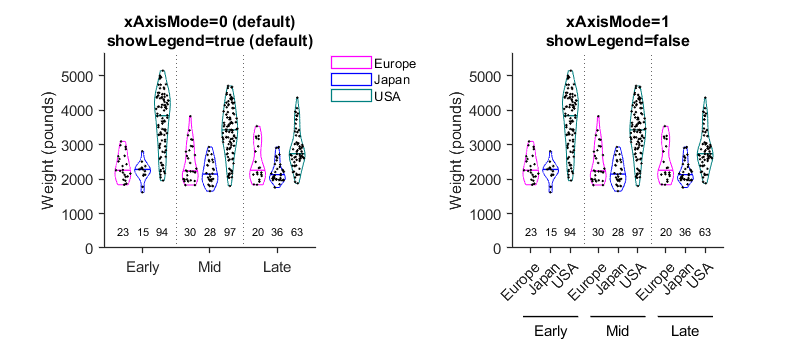

close all

fig = figure("Position",[0 0 800 350]);
layout = tiledlayout(1,2,Padding="loose",TileSpacing="loose");

colors = [1 0 1; 0 0 1; 0 .5 .5];
whenOrder = {'Early','Mid','Late'};
grpandplot(cars,"Weight",yTitle='Weight (pounds)',xFactor="when",cFactor="org",xOrder=whenOrder,...
           showXLine=true,showVln=true,showBox=false,showNum=true,numYPos=500,pntSize=2, ...
           cmap=colors,pntFillC='k',vlnAlpha=0,parent=layout);
title({'xAxisMode=0 (default)' 'showLegend=true (default)'});

t2 = nexttile(layout);  % move to next tile in layout

% Plot in tile2 by assign t2 as the parent
grpandplot(cars,"Weight",yTitle='Weight (pounds)',xFactor="when",cFactor="org",xOrder=whenOrder,...
           showXLine=true,showVln=true,showBox=false,showNum=true,numYPos=500,pntSize=2, ...
           cmap=colors,pntFillC='k',vlnAlpha=0,parent=t2,xAxisMode=1,showLegend=false);
title({'xAxisMode=1' 'showLegend=false'});

### 7.2 Configure figure via MATLAB's Graphics methods and properties

Objects in figures created by `grpandplot` are configurable via MATLAB's Graphics methods and properties. To make configuration easier, you can assign the output of grpandplot to a handle and configure through the handle. The following example assigns the output (i.e. an array of tiles) to a handle named '`tiles`':

close all

fig = figure("Position",[0 0 800 350]);

colors = [1 0 1; 0 0 1; 0 .5 .5];
whenOrder = {'Early','Mid','Late'};
tiles = grpandplot(cars,"Weight",yTitle='Weight (pounds)',xFactor="when",cFactor="org",tFactor="cyl4",xOrder=whenOrder,...
        showXLine=true,showVln=true,showBox=false,showNum=true,numYPos=500,pntSize=2, ...
        cmap=colors,pntFillC='k',vlnAlpha=0,parent=fig,nRow=1,nCol=2,xAxisMode=1,showLegend=false);

The handle `tiles` contains an array of two Axes objects corresponding to the two tiles in the figure. 

You can configure a specfic tile by indexing the tile in `tiles`. For example, rotate x-axis labels in tile 1 and highlight the title of tile 2 in red.

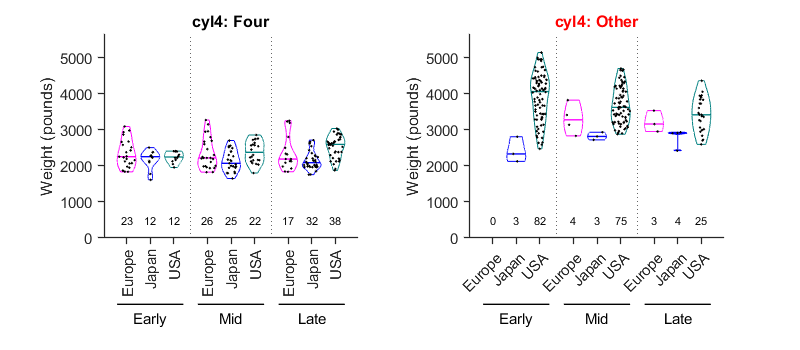

tiles(1).XTickLabelRotation = 90;
tiles(2).Title.Color = 'r';

### 7.3 Configure a specific object in figure

Just like how you would fetch a specific object in any MATLAB figure, you can use the `findobj` method (or function) to configure a specific object in the figure.

close all

fig = figure("Position",[0 0 800 300]);

colors = [1 0 1; 0 0 1; 0 .5 .5];
whenOrder = {'Early','Mid','Late'};
tiles = grpandplot(cars,"Weight",yTitle='Weight (pounds)',xFactor="when",cFactor="org",tFactor="cyl4",xOrder=whenOrder,...
        showXLine=true,showVln=true,showBox=false,showNum=true,numYPos=500,pntSize=2, ...
        cmap=colors,pntFillC='k',vlnAlpha=0,parent=fig,nRow=1,nCol=2);

For example, look for the object, n number '0' in tile 2, with its unique properties (e.g. `String = '0'`) . Change it to red.

% Hightlight the n number '0' in tile 2
nNum = tiles(2).findobj(String='0');
nNum.Color = 'r';

Look for all blue-edged violins in both tiles using their unique properties and change the transparency (alpha) to 0.5.

% Change the transparency (alpha) of blue violins to 0.5
blueViolins = tiles.findobj(Type='patch',EdgeColor=[0 0 1]);  % violin objects are 'patch'
for i = 1:length(blueViolins)  % fill each blue violin with a loop
    blueViolins(i).FaceAlpha = 0.5;
end

Add a title to the legend: 

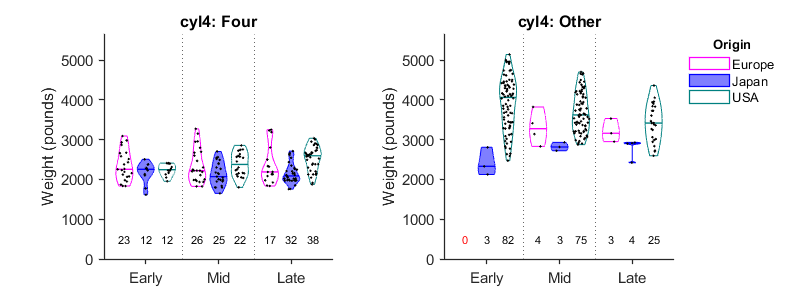

lgd = fig.findobj(Type='legend');
title(lgd,'Origin');

To check the type of an object and a list of properties for a specific type of object, you can open Properties Inspector in the figure window, or visit MATLAB's documentaion.

## 8 License and citation

This tool contains a modified version of `violin.m` created by Jasper Fabius (2019). The copyright notice can be found here: violin/violin_license.txt. Modification is documented in the function file `violin.m`.

This project is licensed under GNU General Public License v3.0.

## Cite As

Wong, M. H. (2022). grpandplot: An open-source MATLAB tool for drawing box plot and violin plot with automatic multi-way data grouping. (Version 1.0.0) [Computer software]. https://doi.org/10.5281/zenodo.7295877